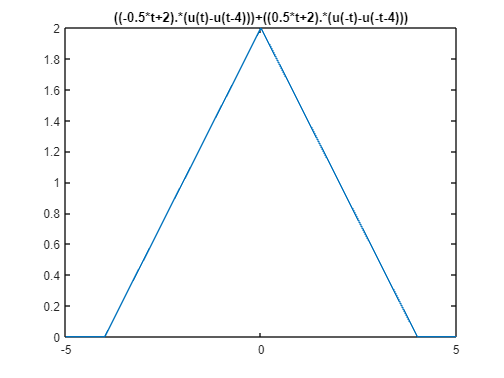

syms w u(t) x(t) r(t) h(t) y(t)
u(t) = heaviside(t);
x(t) =((-0.5*t+2).*(u(t)-u(t-4)))+((0.5*t+2).*(u(-t)-u(-t-4)));
h(t) = ((-0.5*t+1).*(u(t)-u(t-2)))+((0.5*t+1).*(u(-t)-u(-t-2)));
y(t) = int(x(w)*h(t-w), w, -inf, inf);
fplot(x(t))
title('((-0.5*t+2).*(u(t)-u(t-4)))+((0.5*t+2).*(u(-t)-u(-t-4)))')

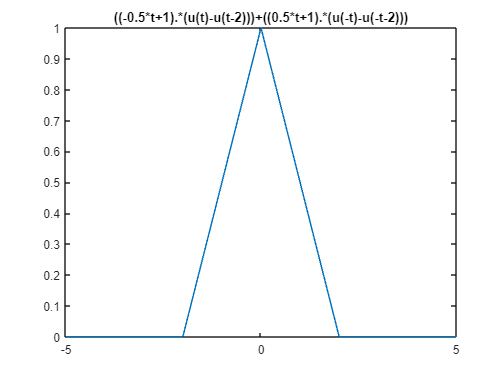

fplot(h(t))
title('((-0.5*t+1).*(u(t)-u(t-2)))+((0.5*t+1).*(u(-t)-u(-t-2)))')

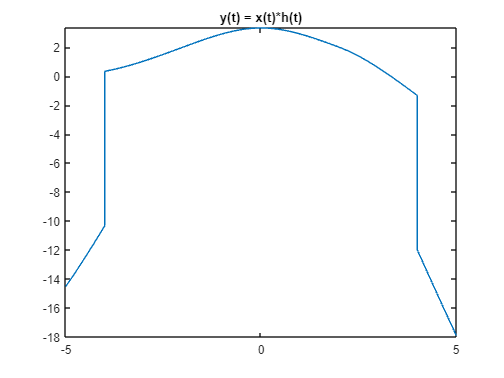

fplot(y(t))
title('y(t) = x(t)*h(t)')